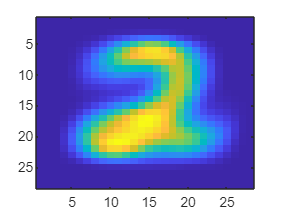

load("mnist.mat")
import mnist.mat.*
mean=(zeros(28*28, 1 ,10));
cov1=zeros(28*28, 28*28, 10);
shape1=(zeros(28*28, 1, 60000));
shape1=reshape(digits_train, size(shape1));
mean=double(mean);
cov1=double(cov1);
shape1=double(shape1);
sizes=zeros(10,1);
for i=1:10
    sizes(i)=sum(labels_train(:,1)==i-1);
end
for i=1:60000
    mean(:, 1, labels_train(i, 1)+1)=mean(:, 1, labels_train(i, 1)+1)+shape1(:, 1, i)/sizes(labels_train(i, 1)+1);
end
for i=1:60000
    cov1(:,:,labels_train(i, 1)+1)=cov1(:,:,labels_train(i, 1)+1)+((shape1(:,1,i)-mean(:,1,labels_train(i, 1)+1))*(shape1(:,1,i)-mean(:,1,labels_train(i, 1)+1))')/sizes(labels_train(i, 1)+1);
end

%shape2=reshape(mean(:, :, 3), [28,28]);
%imagesc(shape2);

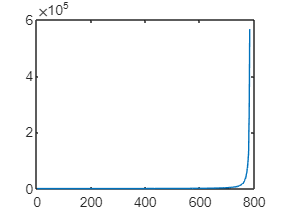


eigenVal1=zeros(28*28, 28*28, 10);
eigenVal1=double(eigenVal1);
eigenVec=zeros(28*28,28*28, 10);
for j=1:10
    [eigenVec(:,:,j),eigenVal1(:,:,j)]=eig(cov1(:, :, j));
end
eigenVal=zeros(28*28, 10);
for k=1:10
    eigenVal(:,k)=diag(eigenVal1(:,:,k));
end
%SortEig(:,:,1)
plot(eigenVal( :, 1));

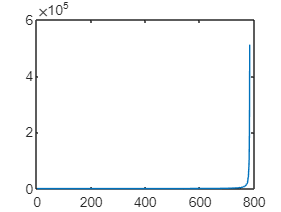

plot(eigenVal( :, 2));

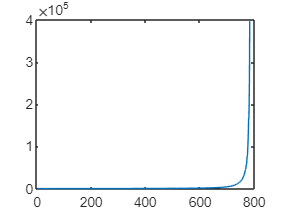

plot(eigenVal( :, 3));

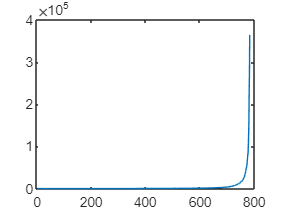

plot(eigenVal( :, 4));

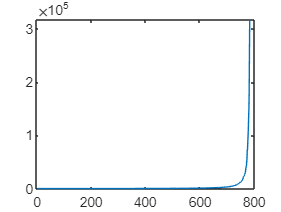

plot(eigenVal( :, 5));

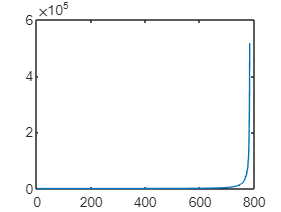

plot(eigenVal( :, 6));

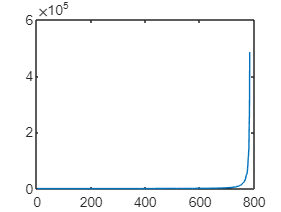

plot(eigenVal( :, 7));

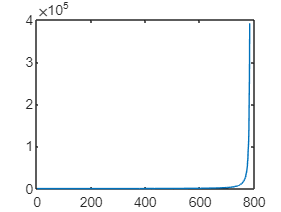

plot(eigenVal( :, 8));

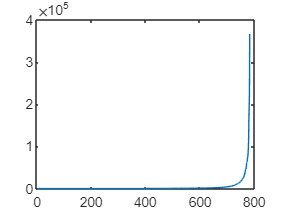

plot(eigenVal( :, 9));

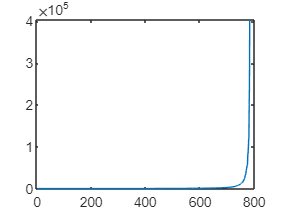

plot(eigenVal(:, 10));

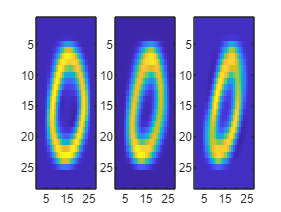

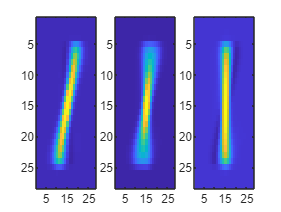

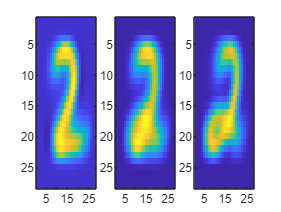

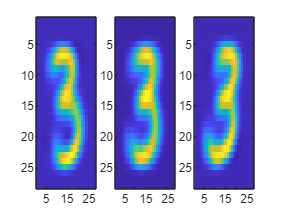

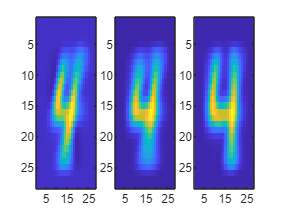

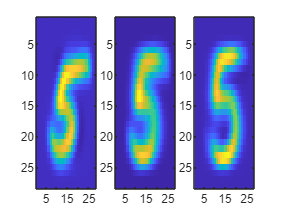

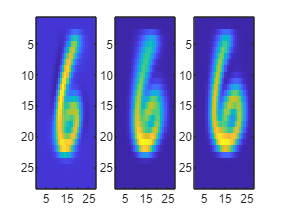

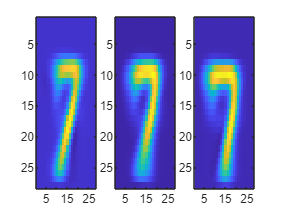


for i=1:10
    figure(i)
    subplot(1, 3, 1), imagesc((reshape((mean(:,1,i)-(sqrt(eigenVal(28*28,i))).*eigenVec(:,28*28, i)),[28,28])));
    subplot(1, 3, 2), imagesc((reshape(mean(:,1,i),[28,28])));
    subplot(1, 3, 3), imagesc((reshape((mean(:,1,i)+(sqrt(eigenVal(28*28,i))).*eigenVec(:,28*28, i)),[28,28])));
end